close all; clear; clc;

# STv5 flight plan #2

**file name**: STv5_TM15d.mlx

**keywords:** settling time, flight plan, secondary

**date of test:** 20180824

**file created by:** 20180830, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** (154:end)

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00228519349876825;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv5_TM15d.mat');
time = STv5_TM15d(:,1);                       % [sec]
PWM = STv5_TM15d(:,2);                        % [micro sec]
Q = STv5_TM15d(:,4);                          % [ft.lbf]
T = STv5_TM15d(:,5);                          % [lbf]
Input_V = STv5_TM15d(:,6);                    % [Volts]
Input_A = STv5_TM15d(:,7);                    % [Amps]
rot_speed_rpm = STv5_TM15d(:,8);              % [RPM]
% convert to rad for calculation purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = STv5_TM15d(:,9);                     % [Watts]
P_out_W = STv5_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv5_TM15d(:,11);                 % [%]
Prop_Eff = STv5_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = STv5_TM15d(:,13);               % [lbf/Watts]  
ESC_Temp = STv5_TM15d(:,14);                  % [F]
Motor_Temp = STv5_TM15d(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

**Settling Time and Max Acceleration**

Settling_time = STv5_TM15d(:,17); % [s]
Max_Acc = STv5_TM15d(:,18);      % [RPM]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

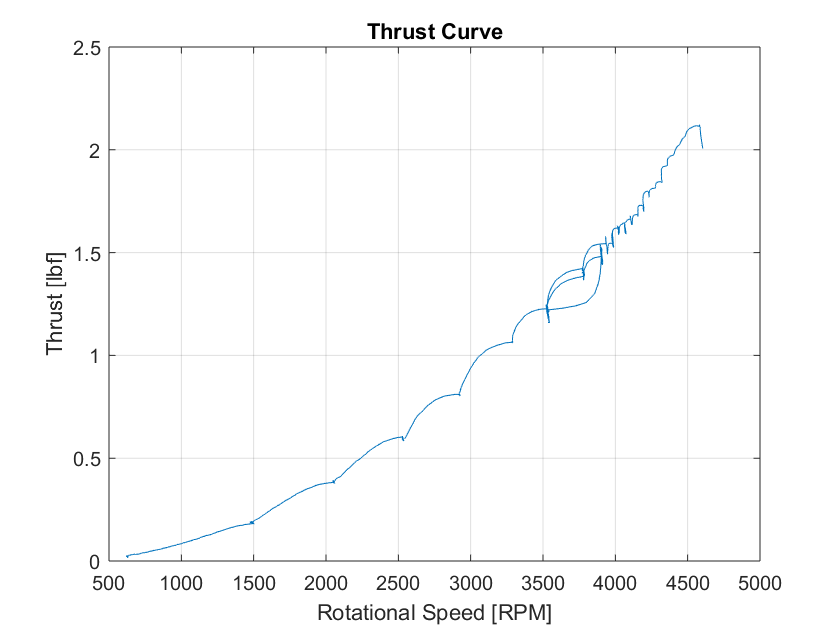

figure(1)
plot(rot_speed_rpm(154:end), T(154:end)); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

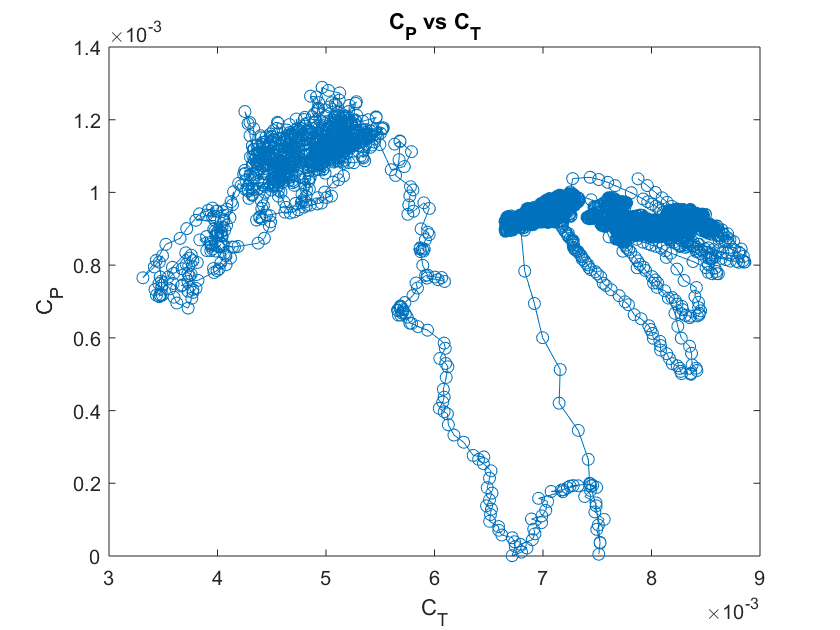


figure(2)
plot(C_T(154:end), C_P(154:end),'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

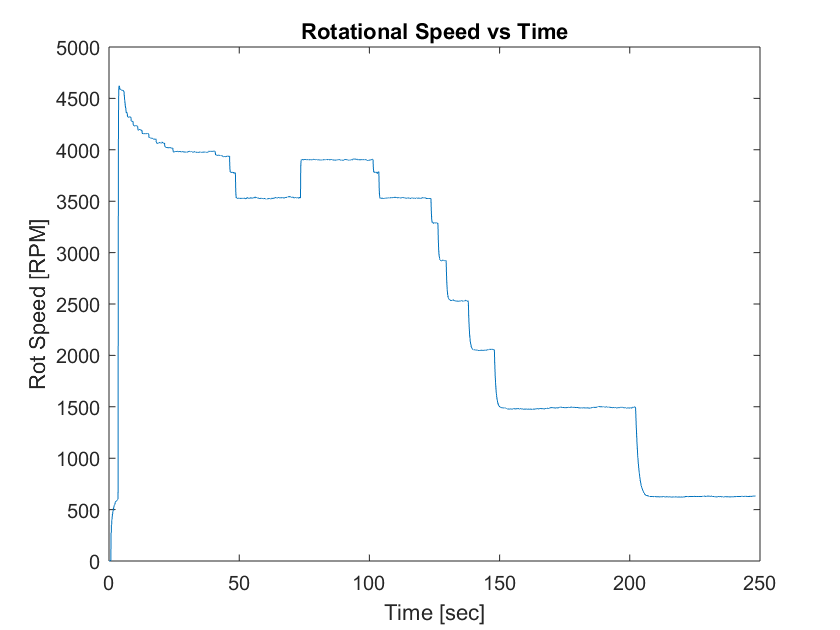


figure(3)
plot(time, rot_speed_rpm); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

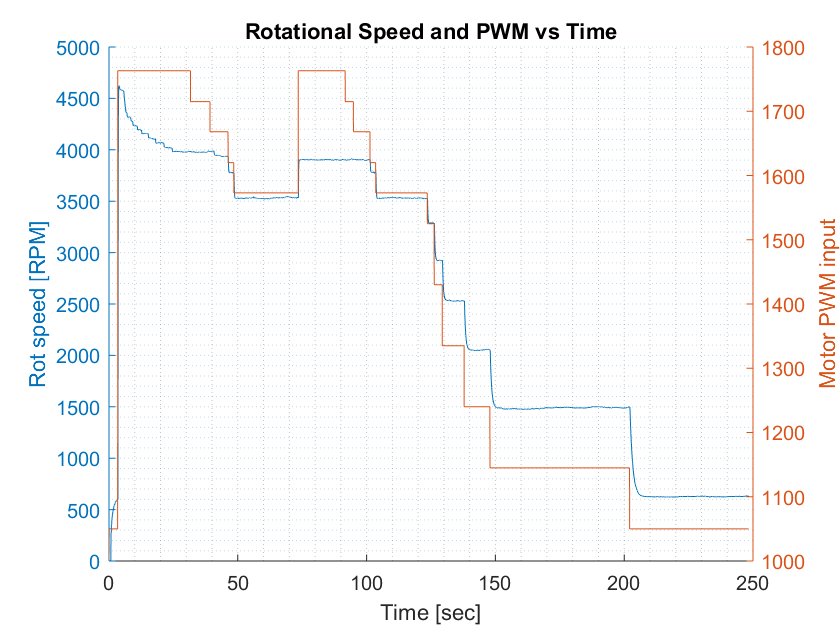


figure(4)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

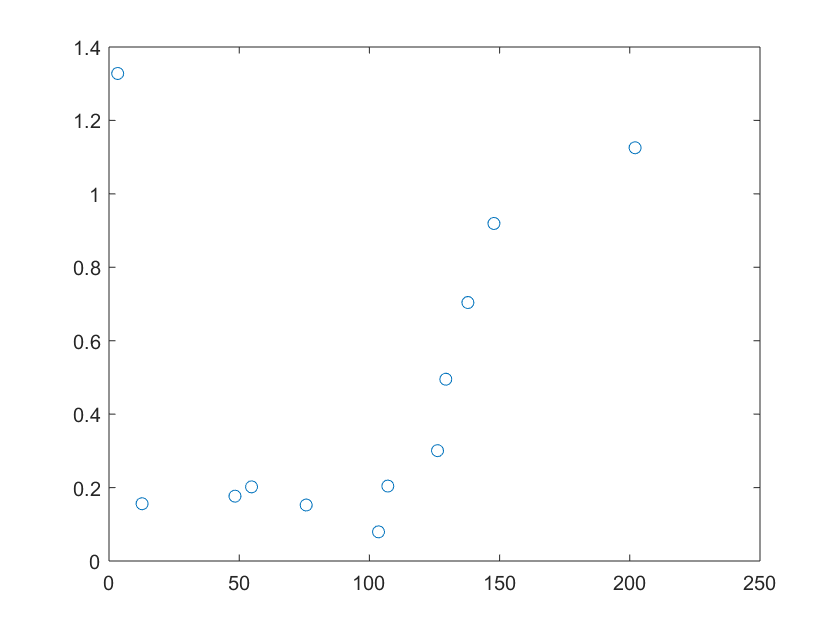



figure(6)
plot(time, Settling_time, 'o-');

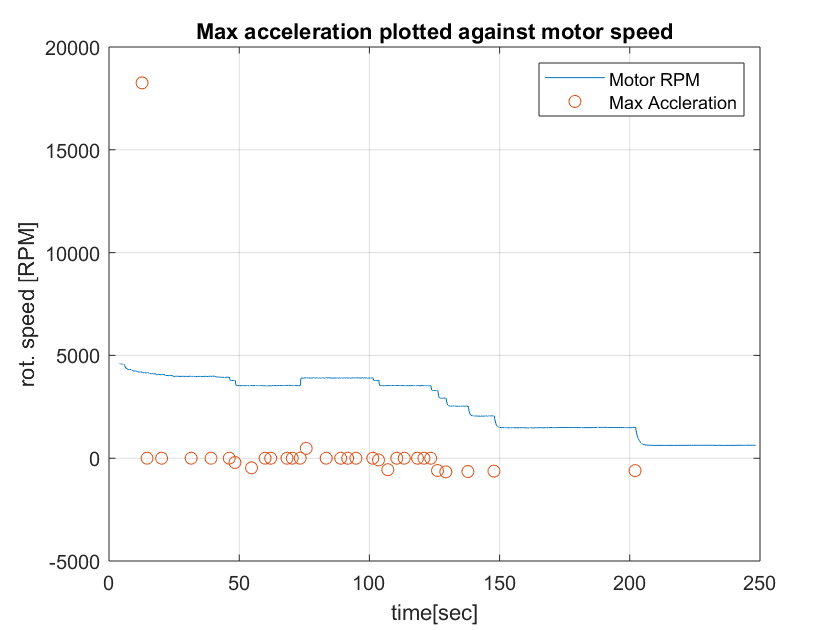


figure(7)
plot(time(154:end), rot_speed_rpm(154:end), time(154:end), Max_Acc(154:end), 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

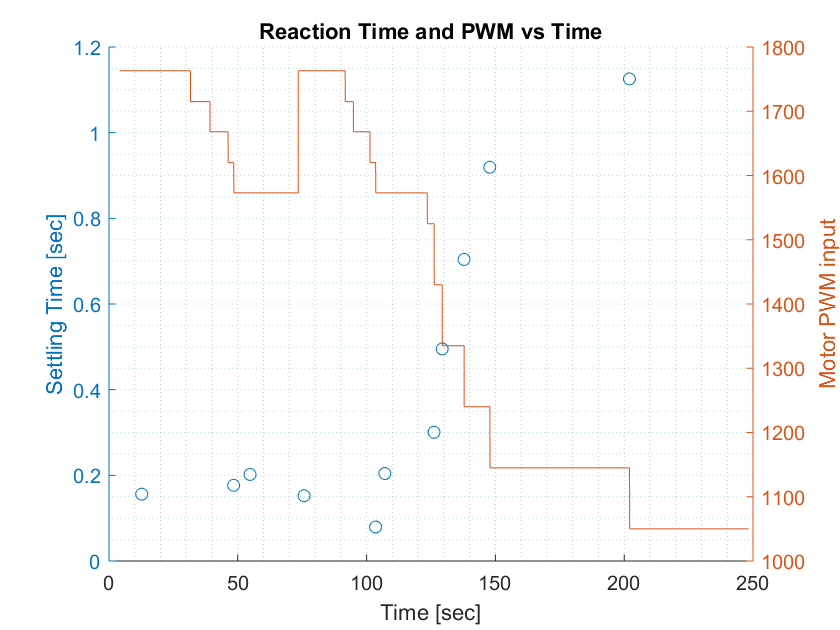


figure(8)
hold on
yyaxis left
plot(time(154:end),Settling_time(154:end), 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time(154:end), PWM(154:end));
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

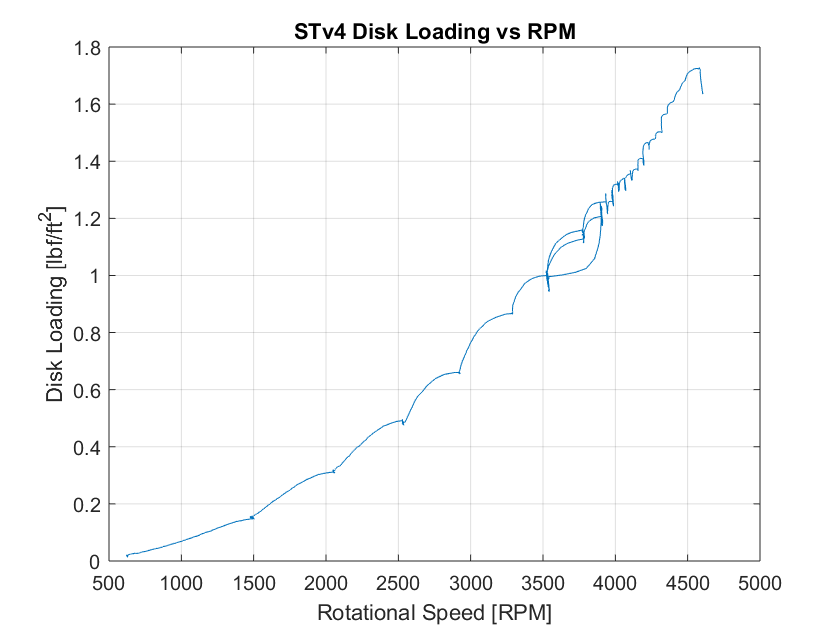


figure(5)
plot(rot_speed_rpm(154:end), disk_loading(154:end)); title('STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

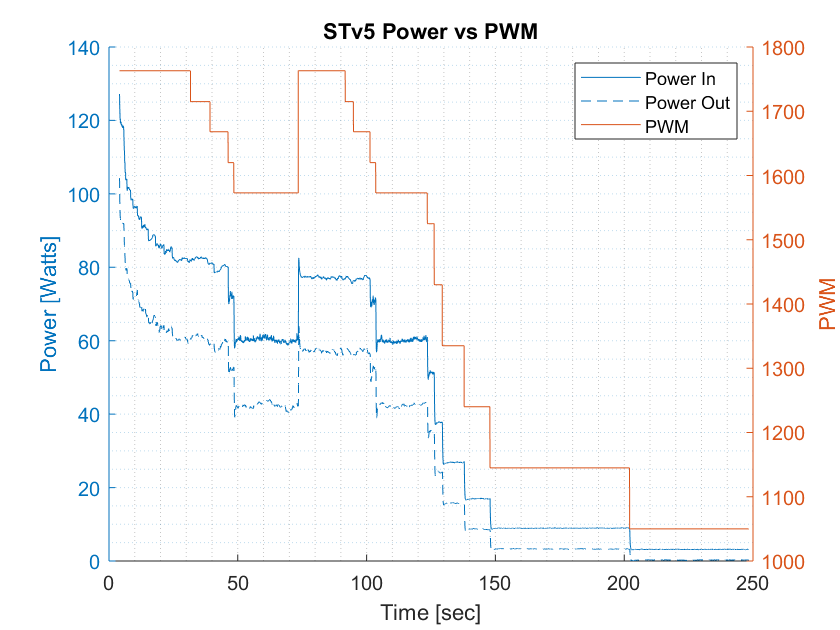


figure(9)
hold on
yyaxis left
plot(time(155:end), P_in_W(155:end), time(155:end), P_out_W(155:end));
ylabel('Power [Watts]');
legend('Power In', 'Power Out')
yyaxis right
plot(time(155:end), PWM(155:end), 'DisplayName','PWM');
ylabel('PWM');
title('STv5 Power vs PWM');
xlabel('Time [sec]');
grid('minor');
hold off

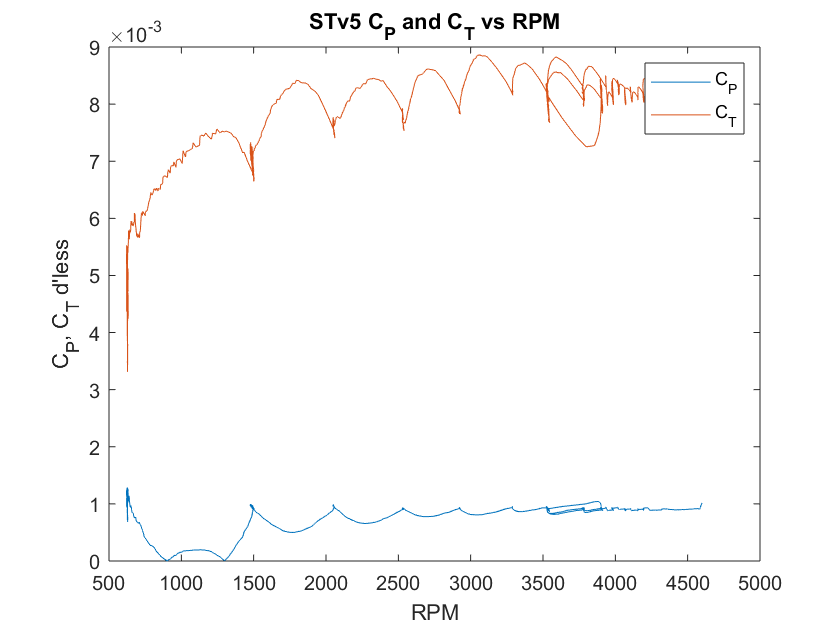


figure(10)
plot(rot_speed_rpm(155:end), C_P(155:end), rot_speed_rpm(155:end), C_T(155:end));
title('STv5 C_P and C_T vs RPM'); legend('C_P', 'C_T');
xlabel('RPM'); ylabel("C_P, C_T d'less");

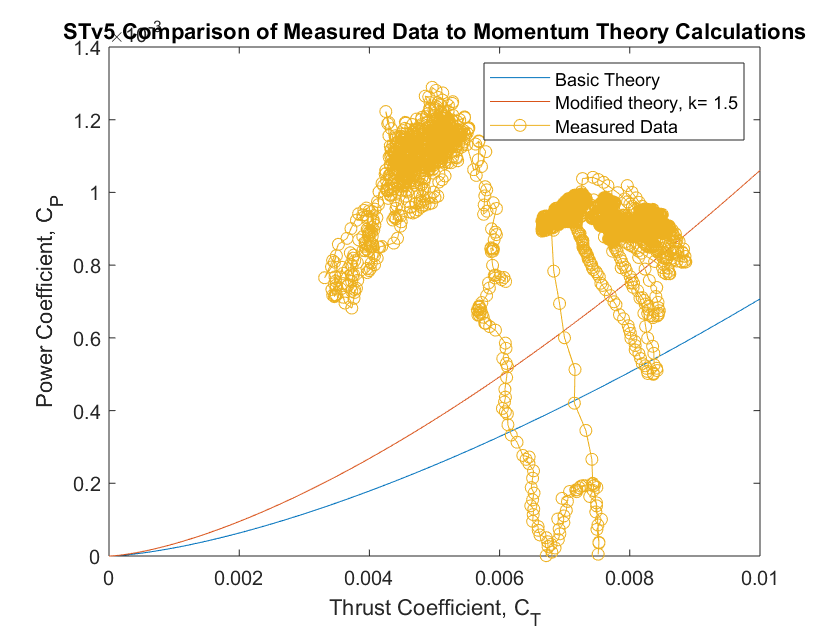

k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(13)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T(155:end), C_P(155:end), 'o-');
title('STv5 Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data');